# 4. 2次元フーリエ変換とフーリエ領域でのフィルタリング

clear;
clf;
getd = @(p)path(p,path);
getd('toolbox_signal/');
getd('toolbox_general/');
rng('default');

## 離散フーリエ変換

ディジタル信号を周波数領域へ変換するためには，以下で定義される**離散フーリエ変換** (discrete Fourier transform: DFT) がよく用いられる（詳細の説明は来年度の講義「信号とシステム」，「ディジタル信号処理」で行う）．

$y[k] = \sum_{n=0}^{N-1} x[n]W_{N}^{kn}$                    (1)

ここで$x[n]\ (n = 0,\dots, N-1)$ は入力信号（ベクトル），$y[n]$は出力信号（フーリエ係数と呼ばれる），$W_{N} = e^{-j\frac{2\pi}{N}}$である（ここで$j$は虚数単位）．DFTは可逆変換（フーリエ係数から原信号が復元可能）であり，逆DFTは以下で定義される．


$$x[n] = \frac{1}{N}\sum_{k=0}^{N-1} y[k]W_{N}^{-kn}$$


画像のような2次元信号（行列）に対してDFTを行う際は，まず 1) 各列をベクトルとみなしてDFTを行った後に，2) 各行に対してDFTを行えばよい．

ここで実際にMATLAB上で画像に対してDFTを行ってみよう．2次元信号用に，`fft2`という関数が利用できる．

※ FFTは fast Fourier transform（高速フーリエ変換）の略で，DFTを高速に行うアルゴリズム．

name = 'house';
u = load_image(name, []);
n = length(u);
uf = fft2(u);

まずは絶対値をスケーリングしてそのまま表示してみる．

clf;
uf_abs = abs(uf);
imageplot(rescale(uf_abs), 'DFT');

ほぼ黒に見えるのは，画像信号のエネルギーがDFTによって1箇所に集中しているからである．以下のように左上の10x10のフーリエ係数を見てみる．

uf_abs(1:10,1:10)

ans = 1.0e+06 *

    7.2448    0.8734    0.6211    0.4324    0.3112    0.2950    0.2355    0.3120    0.2370    0.1198
    0.6228    0.2175    0.5157    0.3603    0.1972    0.2631    0.1462    0.1384    0.0463    0.0932
    0.3547    0.0769    0.0384    0.1411    0.2470    0.1985    0.2519    0.0867    0.0694    0.1463
    0.2959    0.0486    0.1797    0.1102    0.1339    0.1453    0.1457    0.1583    0.0774    0.0392
    0.0300    0.1059    0.1536    0.0692    0.1045    0.0574    0.0343    0.0979    0.1718    0.1614
    0.0670    0.0903    0.0425    0.0445    0.0606    0.0405    0.0111    0.0299    0.0380    0.0723
    0.0051    0.0725    0.0336    0.0913    0.0013    0.0261    0.0682    0.0315    0.0259    0.0304
    0.1274    0.1388    0.0297    0.0296    0.0546    0.0182    0.0090    0.0333    0.0308    0.0173
    0.0892    0.0156    0.0274    0.0404    0.0248    0.0283    0.0424    0.0354    0.0168    0.0167
    0.0345    0.0784    0.0264    0.0190    0.0210    0.0101    0.0290    

左上のフーリエ係数が他の係数の10倍〜数百倍となっており，右下にいくに従って急激にエネルギーが減少していることがわかる．フーリエ変換の定義より，左上は画素値の平均値（の定数倍）が出力されており，右下にいくに従って高い周波数の成分が格納されている．この結果から，**画像には低い周波数，つまり滑らかに変動する成分だけしか（ほとんど）含まれていない**ことがわかる．

ここで，見やすいように`fftshift`を使って最も低い周波数成分を中心に移動した後に，対数スケールで係数を表示してみよう．

help fftshift

 fftshift Shift zero-frequency component to center of spectrum.
    For vectors, fftshift(X) swaps the left and right halves of
    X.  For matrices, fftshift(X) swaps the first and third
    quadrants and the second and fourth quadrants.  For N-D
    arrays, fftshift(X) swaps "half-spaces" of X along each
    dimension.
 
    fftshift(X,DIM) applies the fftshift operation along the 
    dimension DIM.
 
    fftshift is useful for visualizing the Fourier transform with
    the zero-frequency component in the middle of the spectrum.
 
    Class support for input X:
       float: double, single
 
    See also ifftshift, fft, fft2, fftn, cir

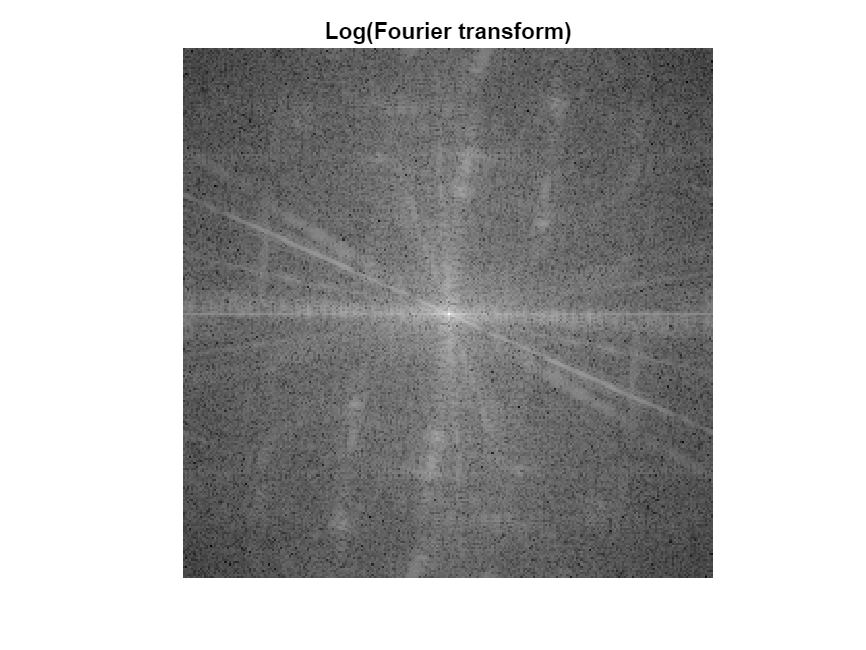

umflog = fftshift(log( abs(uf)+0.01e-1 )); % log(0) を防ぐために微小正数を加算
figure;
imageplot(umflog, 'Log(Fourier transform)');

この場合，中心から外に向かうに従って周波数が高くなった成分が表示される．

フーリエ変換は変換の前後でエネルギー（ユークリッドノルム or L2ノルム）が保存される．

※ 画像のエネルギー：画素値の2乗和

disp(strcat(['Energy of Image:   ' num2str(norm(u(:)))]));

Energy of Image:   31353.0989


disp(strcat(['Energy of Fourier: ' num2str(norm(uf(:))/n)]));

Energy of Fourier: 31353.0989


% nで割っているのは定数倍を正規化するため

## フーリエ領域でのフィルタリング

フーリエ変換は線形の操作※なので，式(1)は行列とベクトルを用いて以下のようにも表現できる．

※ 行列で変換が表現できる，として考えればよい．


$$\mathbf{y} = \mathbf{Wx}$$


ここで


$$\mathbf{x} = [x[0], x[1], x[2], \ldots, x[N-1]]^\top$$



$$\mathbf{y} = [y[0], y[1], y[2], \ldots, y[N-1]]^\top$$



$$\mathbf{W}=\left\lbrack \begin{array}{cccc}
1 & 1 & \cdots  & 1\\
1 & W_N  & \cdots  & W_N^{N-1} \\
\vdots  &  & \ddots  & \\
1 & W_N^{N-1}  & \cdots  & W_N^{{\left(N-1\right)}^2 } 
\end{array}\right\rbrack$$


ここで$W_N = e^{-j\frac{2\pi}{N}}}$，$\cdot^{\top}$は行列（ベクトル）の転置である．フーリエ変換の定義と見比べて，同一の処理になっていることを確認しよう．

ここで，2次元の入力画像を行列


$$\mathbf{X}=\left\lbrack \begin{array}{cccc}
x\left\lbrack 0,0\right\rbrack  & x\left\lbrack 0,1\right\rbrack  & \cdots  & x\left\lbrack 0,N-1\right\rbrack \\
x\left\lbrack 1,0\right\rbrack  & x\left\lbrack 1,1\right\rbrack  & \cdots  & x\left\lbrack 1,N-1\right\rbrack \\
\vdots  &  & \ddots  & \\
x\left\lbrack N-1,0\right\rbrack  & x\left\lbrack N-1,1\right\rbrack  & \cdots  & x\left\lbrack N-1,N-1\right\rbrack 
\end{array}\right\rbrack$$


として表現すると，画像に対するDFTは以下のように表されることがわかる．


$$\mathbf{Y} = \mathbf{WXW}^\top$$
   

この$\mathbf{Y}$を用いて，画像をフーリエ領域でフィルタリングしてみよう．

ここで見たように，画像には低周波数成分が多く含まれているのであった．ここでは，低周波数成分だけを通すフィルタ（低域通過フィルタ）を$\mathbf{Y}$に適用してみよう．

まず，残す周波数成分の数 $M$ を定め，対応する正方領域を定義する．

M = n^2/16; % 残す周波数成分の数
m = sqrt(M);
umf = zeros(n,n);
sel = (n/2-m/2:n/2+m/2)+1;

次に抽出した$M$ 個のフーリエ係数だけから画像を再構成（逆フーリエ変換）し，結果を表示する．

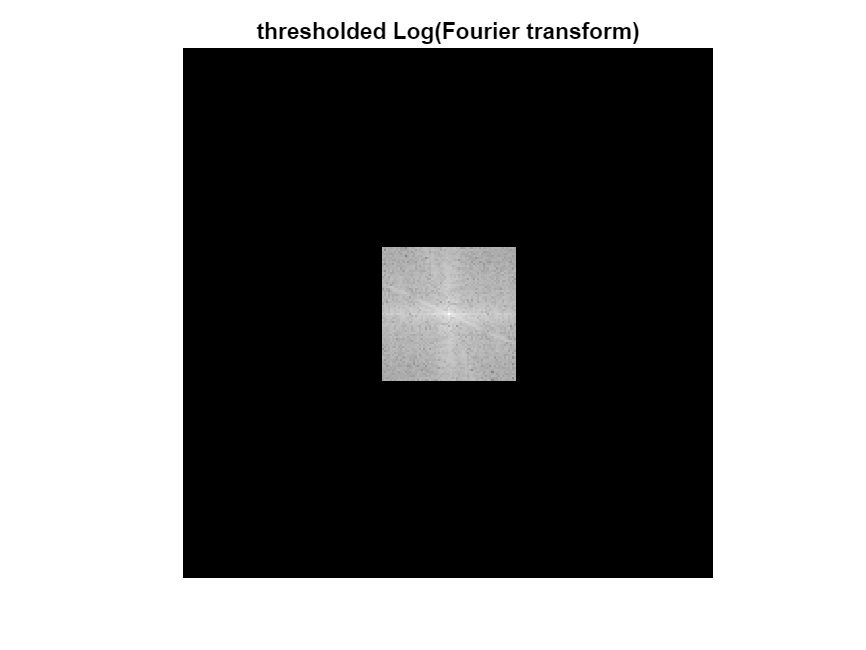

uf = fftshift(fft2(u));
umf(sel,sel) = uf(sel,sel);
figure;
umflog = log( abs(umf)+0.01e-1 );
imageplot(umflog, 'thresholded Log(Fourier transform)');

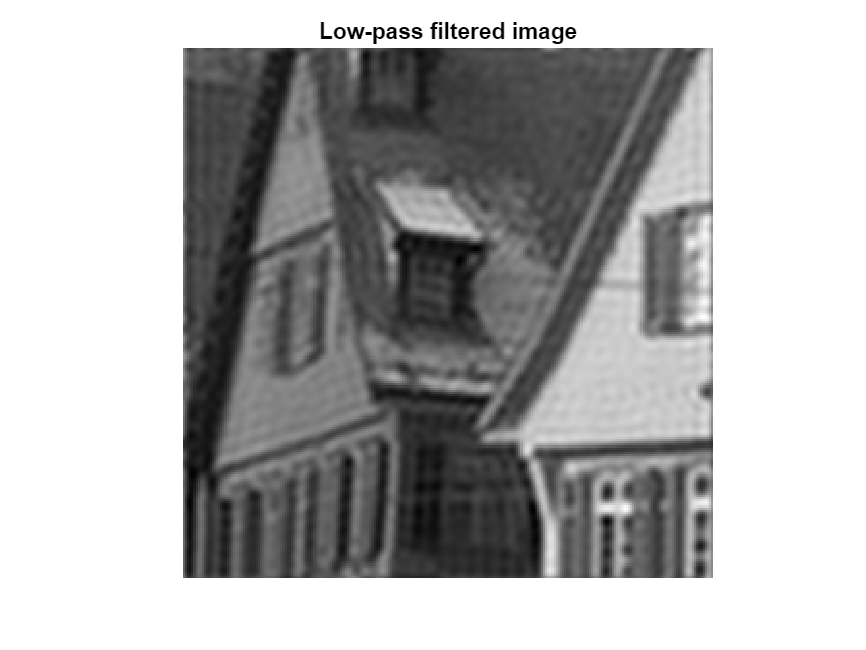

um = real( ifft2(ifftshift(umf)) );
%ifftshift は fftshift でずらした係数を元に戻す関数
figure;
imageplot(um, 'Low-pass filtered image');

前回の画素領域でのフィルタリングと同様に，画像がなめらかになっている（ぼけている）ことがわかる．原画像との画質を定量的に（＝数値的に）比較する際には，peak-signal-to-noise ratio (PSNR：単位はデシベル [dB]) が利用されることが多い（PSNRが大きいほうが画質が高い）．

help psnr

  psnr - compute the Peack Signal to Noise Ratio
 
    p = psnr(x,y,vmax);
 
    defined by :
        p = 10*log10( vmax^2 / |x-y|^2 )
    |x-y|^2 = mean( (x(:)-y(:)).^2 )
    if vmax is ommited, then
        vmax = max(max(x(:)),max(y(:)))
 
    Copyright (c) 2004 Gabriel Peyre

    psnr のその他の使用



result = sprintf('%s %.2f %s', 'PSNR=', psnr(u,um), 'dB');
fprintf(result);

PSNR= 22.53 dB

## 演習問題

**演習4-1**: グレースケール画像'house'を読み込み，フーリエ領域で**高域**通過フィルタを実行せよ．残す周波数成分の数 $M$ を画素数の3/4，15/16に設定したとき，

- 残した $M$ 個の周波数成分（対数スケールかつ低周波成分を中心に配置すること）

- それらを使って求めた高域通過画像とそのPSNR [dB]

を表示せよ．

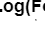

%3/4
name = 'house';
u = load_image(name, []);
n = length(u);

M = n^2/4*3; % 残す周波数成分の数
m = sqrt(M);
umf = zeros(n,n);
sel = round((n/2-m/2:n/2+m/2)+1);

uf = fftshift(fft2(u));
umf(sel,sel) = uf(sel,sel);
figure;
umflog = log( abs(umf)+0.01e-1 );
imageplot(umflog, 'thresholded Log(Fourier transform)');

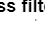

um = real( ifft2(ifftshift(umf)) );

figure;
imageplot(um, 'Low-pass filtered image');


result = sprintf('%s %.2f %s', 'PSNR=', psnr(u,um), 'dB');
fprintf(result);

PSNR= 36.74 dB


%15/16

M = n^2/16*15; % 残す周波数成分の数
m = sqrt(M);
umf = zeros(n,n);
sel = round((n/2-m/2:n/2+m/2)+1);

uf = fftshift(fft2(u));
umf(sel,sel) = uf(sel,sel);
figure;
umflog = log( abs(umf)+0.01e-1 );
imageplot(umflog, 'thresholded Log(Fourier transform)');

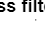

um = real( ifft2(ifftshift(umf)) );

figure;
imageplot(um, 'Low-pass filtered image');


result = sprintf('%s %.2f %s', 'PSNR=', psnr(u,um), 'dB');
fprintf(result);

PSNR= 42.37 dB

**演習4-2**: 上記の高域通過フィルタを行った画像を利用し，輪郭を強調した画像を生成して表示せよ．

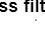

%1/16の画素を使用した低周波画像を元の画像から引く

M = n^2/16; % 残す周波数成分の数
m = sqrt(M);
umf = zeros(n,n);
sel = round((n/2-m/2:n/2+m/2)+1);

uf = fftshift(fft2(u));
umf(sel,sel) = uf(sel,sel);
um = real( ifft2(ifftshift(umf)) );
highuf = uf - umf;

highum = real( ifft2(ifftshift(highuf)) );

figure;
imageplot(highum, 'High-pass filtered image');

**演習4-3**: 画像に対する離散フーリエ変換・逆離散フーリエ変換を行うプログラムを自分で作成せよ．逆離散フーリエ変換したときに，原画像が復元できていることを確認せよ（PSNR が 300 dB 程度であれば成功している）．

また，グレースケール画像'house'に対して離散フーリエ変換を実行したときの時間を計測し，`fft2の`実行時間と比較せよ．

**    演習4-3は 5. の課題と同時に提出してもよい（＝2週間かけてもよい）．**

ヒント：実行時間は `tic toc` コマンドで測れる．

name = 'house';
u = load_image(name, []);
tic;
[M, N] = size(u);
uxf = zeros(M, N);
for i = 1:M
    for j = 1:N
        sum_val = 0;
        for x = 1:M
            sum_val = sum_val + double(u(x, j)) * exp(-1j * 2 * pi * (i-1)*(x-1)/M);
        end
        uxf(i, j) = sum_val;
    end
end
uf = zeros(M, N);
for i = 1:M
    for j = 1:N
        sum_val = 0;
        for y = 1:N
            sum_val = sum_val + double(uxf(i, y)) * exp(-1j * 2 * pi * (j-1)*(y-1)/N);
        end
        uf(i, j) = sum_val;
    end
end
toc;

経過時間は 12.227541 秒です。


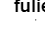

PSNR= 5.66 dB


[M, N] = size(u);
uxif = zeros(M, N);
for i = 1:M
    for j = 1:N
        sum_val = 0;
        for x = 1:M
            sum_val = sum_val + double(uf(x, j)) * exp(1j * 2 * pi * (i-1)*(x-1)/M);
        end
        uxif(i, j) = sum_val;
    end
end
uif = zeros(M, N);
for i = 1:M
    for j = 1:N
        sum_val = 0;
        for y = 1:N
            sum_val = sum_val + double(uxif(i, y)) * exp(1j * 2 * pi * (j-1)*(y-1)/N);
        end
        uif(i, j) = sum_val;
    end
end
% 結果の表示
figure;
imageplot(real(uif), 'fulier');


tic;
uf = fft2(u);
toc;

経過時間は 0.002215 秒です。
